# Solving for 4th order stuff

Initial varibales

t_s = 0.01; % take time constant and make 10 times smaller, to be faster
m_p = 0.05; %[percent off]
tau = 0.1134; % seconds
r = 35; %mm
k = 3.27 ;% motor constant, need to calc rad/volt-sec
w = 141;% mm
t_step = 0.05% seconds for period to run task , Using per = 100

t_step = 0.0500


%%% X_hat = [omega_l, omega_r, S(arclength), shi]^-1%%%

A = [ -1/tau,  0,     0, 0;  
       0,    -1/tau,  0, 0;
       r/2,   r/2,    0, 0;
      -r/w,   r/w,    0, 0 ];

B = [  k/tau, 0;
       0,     k/tau;
       0,     0;
       0,     0 ];

c = [ 0, 0, 1, -w/2;
      0, 0, 1,  w/2;
      0, 0, 0,  1;
     -r/w, r/w, 0,  0 ];

d = zeros(4,2);



zeta = (-log(m_p))/((pi()^2 + (log(m_p))^2)^(1/2))

zeta = 0.6901

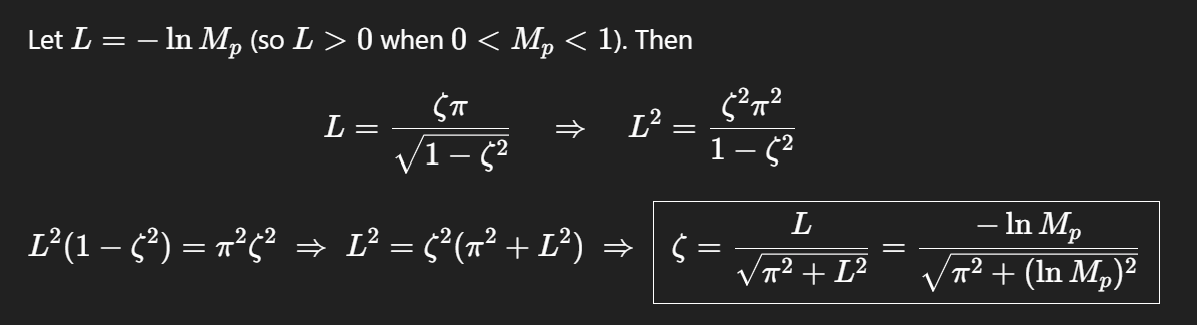

ln(mp) = -hpie/

omega = (3/(zeta*t_s)) % use 3 for 95% certainty, and 4 for 95% cert

omega = 434.7154

now need to solve for 2 poles and place 2 poles far away

poles are solutions/eignevalues/ roots to the characterisitc eqution

a1 = 2 zeta omega, a0 = w^2

a_1 = 2*zeta*omega

a_1 = 600.0000

a_0 = omega^2

a_0 = 1.8898e+05


poles = roots([1, a_1,a_0]);
pol_1 = poles(1)

pol_1 = -3.0000e+02 + 3.1461e+02i

pol_2 = poles(2)

pol_2 = -3.0000e+02 - 3.1461e+02i

disp(poles)

   1.0e+02 *

  -3.0000 + 3.1461i
  -3.0000 - 3.1461i



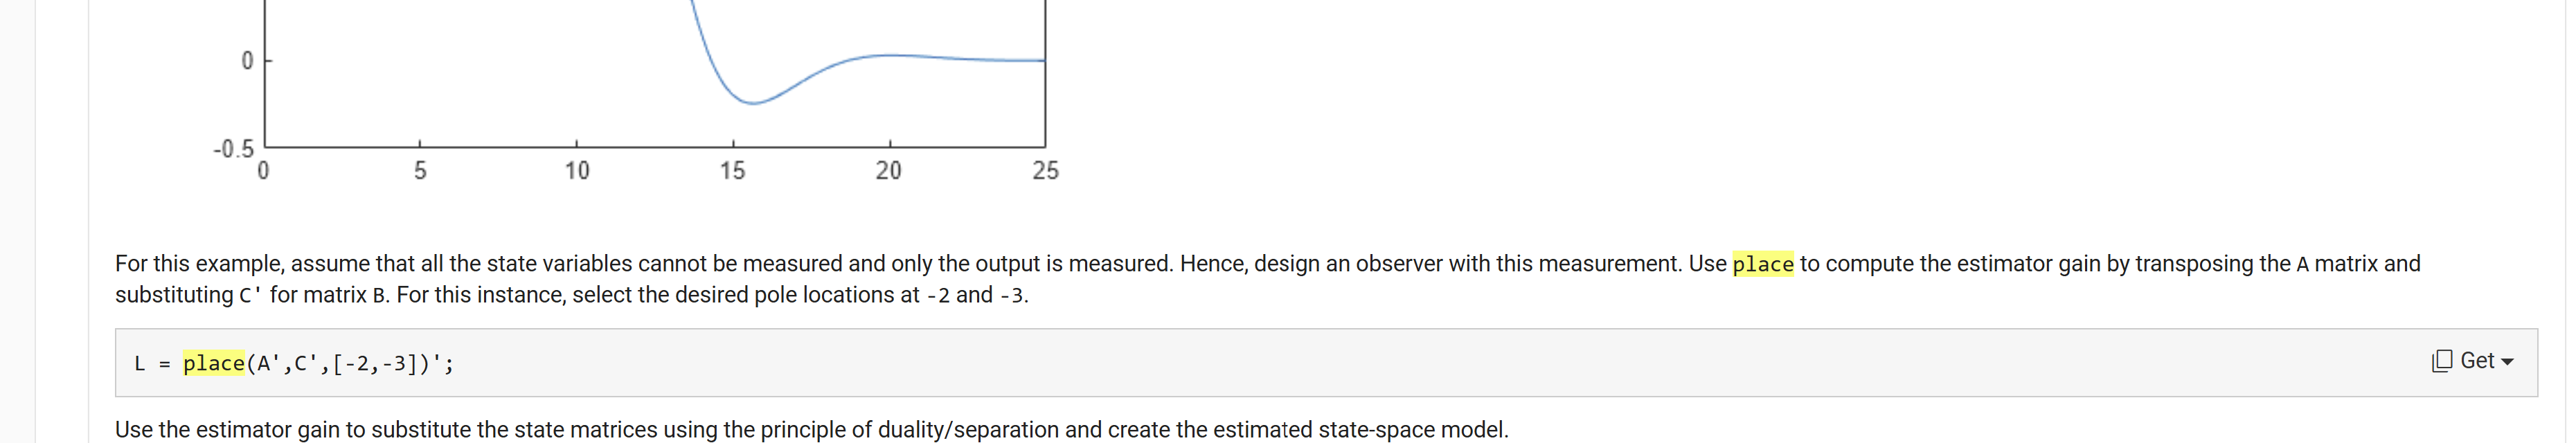

pol_3 = -10*omega

pol_3 = -4.3472e+03

pol_4 = -10 *omega + 1

pol_4 = -4.3462e+03


L = place(A',c',[pol_1,pol_2, pol_3,pol_4])';

Observer

A_0 = (A - L*c)

A_0 = 1.0e+03 *

   -2.1775    2.1687   -5.2504    0.0000
    2.1687   -2.1775   -5.2504    0.0000
    0.0175    0.0175   -0.5912    0.0000
    0.0000   -0.0000    0.0000   -4.3472


B_0 = [B - L*d,L]

B_0 = 1.0e+03 *

    0.0288         0    2.6252    2.6252   -0.0000   -8.7366
         0    0.0288    2.6252    2.6252    0.0000    8.7366
         0         0    0.2956    0.2956   -0.0000   -0.0000
         0         0   -0.0308    0.0308    0.0004    0.0010


disp(L)

   1.0e+03 *

    2.6252    2.6252   -0.0000   -8.7366
    2.6252    2.6252    0.0000    8.7366
    0.2956    0.2956   -0.0000   -0.0000
   -0.0308    0.0308    0.0004    0.0010



% make delta t eq to expected run frequency.
% to be incorporated into python battery 7.4 to 8.4
% kp should be under 4 by alittle






sysc = ss(A_0,B_0, c,0)


sysc =
 
  A = 
               x1          x2          x3          x4
   x1       -2177        2169       -5250   3.043e-11
   x2        2169       -2177       -5250   2.781e-11
   x3        17.5        17.5      -591.2   7.278e-12
   x4   1.726e-13  -1.726e-13   3.464e-12       -4347
 
  B = 
               u1          u2          u3          u4          u5          u6
   x1       28.84           0        2625        2625  -1.323e-12       -8737
   x2           0       28.84        2625        2625   1.289e-12        8737
   x3           0           0       295.6       295.6  -2.098e-15  -3.046e-12
   x4           0           0      -30.83       30.83      0.4373           1
 
  C = 
            x1       x2       x3       x4
   y1        0        0        1    -70.5
   y2        0        0        1     70.5
   y3        0        0        0        1
   y4  -0.2482   0.2482        0        0
 
  D = 
       u1  u2  u3  u4  u5  u6
   y1   0   0   0   0   0   0
   y2   0   0   0   0   0 

sysd =c2d(sysc,t_step, 'zoh');
[A_D, B_d,C_d, D_D] = ssdata(sysd);

A_D

A_D = 1.0e-06 *

   -0.1561   -0.1561    0.1142   -0.0000
   -0.1561   -0.1561    0.1142   -0.0000
   -0.0004   -0.0004   -0.2995   -0.0000
    0.0000    0.0000   -0.0000   -0.0000


B_d

B_d =     0.0484    0.0418   -0.0000   -0.0000   -0.0000   -2.0102
    0.0418    0.0484   -0.0000   -0.0000    0.0000    2.0102
    0.0027    0.0027    0.5000    0.5000   -0.0000    0.0000
    0.0000    0.0000   -0.0071    0.0071    0.0001    0.0002


C_d

C_d =          0         0    1.0000  -70.5000
         0         0    1.0000   70.5000
         0         0         0    1.0000
   -0.2482    0.2482         0         0


D_D

D_D =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
